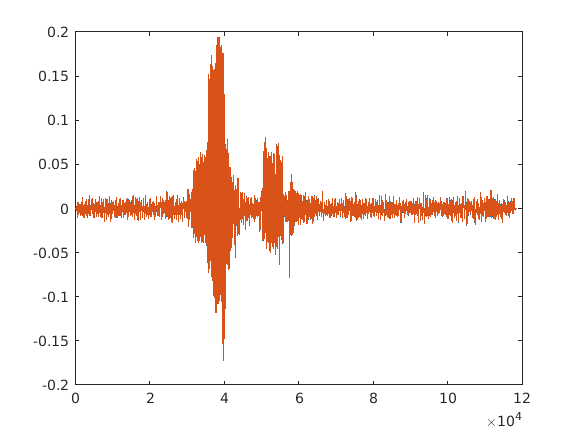

[zvuk fs]=audioread('nektar.m4a'); 

dt = 1/fs;  %korak uzorkovanja
N=size(zvuk,1); %broj uzoraka 
t = (0:N-1)*dt; %vektor vremena
plot(zvuk);

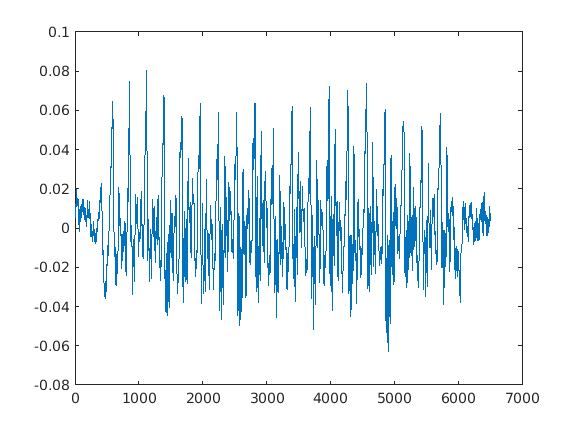


x_uzorak=zvuk(50000:56500);

plot(x_uzorak);

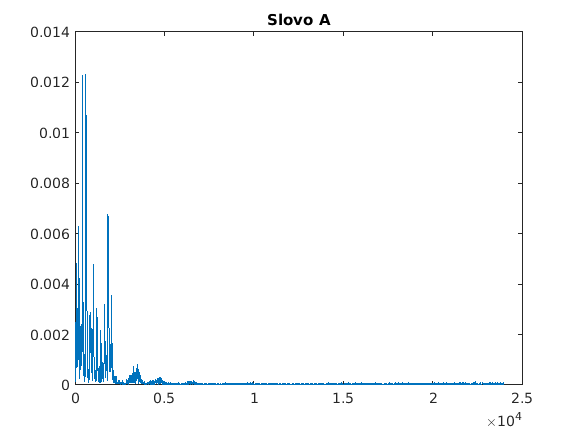

Y=abs(fft(x_uzorak));
N1=5246;
P2=Y/N1;
P1=P2(1:N1/2+1);
P1(2:end-1)=2*P1(2:end-1);
f=fs*(0:(N1/2))/N1;
plot(f,P1);
title('Slovo A');